## **EEGLAB OpenNeuro to DL pipeline**

In this example, we present the pipeline that downloads the [EEG dataset](https://openneuro.org/datasets/ds003061/versions/1.1.2) from [OpenNeuro](https://docs.openneuro.org/user_guide.html) archive [1], pre-processes it using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php) toolbox [2] and formats as input for deep learning-based classification. The data was collected at the Meditation Research Institute (MRI) in Rishikesh, India under the supervision of Arnaud Delorme, PhD ([Swartz Center for Computational Neuroscience](https://sccn.ucsd.edu/)). The data is stored in a [BIDS](https://bids.neuroimaging.io/) format [3], a standard defining the organization of neuroimaging/accompanying behavioral data, as well as the relevant metadata, facilitating the data sharing and reproducibility.

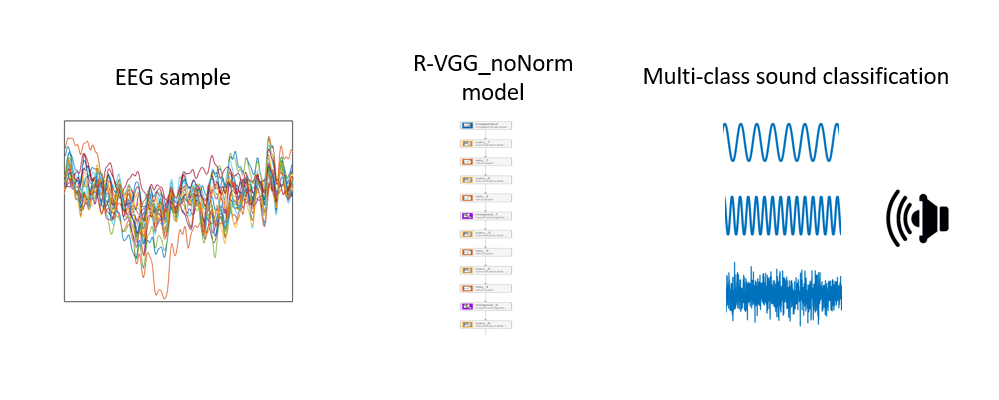

**Background on Dataset**

The dataset consists of a scalp EEG recordings from 13 participants, each providing 3 13-min sessions. Participants were asked to keep the eyes closed during recording, while being presented with 750 **auditory stimuli**, divided in 3 groups: **standard **(500 Hz pure tone lasting 60 ms), **oddball** (1000 Hz pure tone lasting 60 ms) and **distractors** (white noise lasting 60 ms). Sounds were presented at 1/sec rate. Participants were instructed to respond to oddball tone using a key press. 

Recording was performed using the standard [**10-20 EEG system**](https://en.wikipedia.org/wiki/10%E2%80%9320_system_(EEG)) (Active Two Biosemi system, Biosemi Inc.), with 1024 Hz sampling rate. The data in OpenNeuro dataset was subsequently resampled at 256 Hz. Individual samples consist of 1 sec signal across 144 channels, spanning the time window between the two consecutive tone onsets.

**Background on Example**

In this example, we are demonstrating the multi-class (more than two classes) classification of auditory stimuli based on the scalp EEG recordings. For each stimulus, the time window of 0-0.5 sec relative to stimulus onset is used for model training/inference. 

**BIDS Format**

BIDS format [3] defines the dataset structure and minimum information the dataset needs to contain. The EEG data files could be stored as one of the standard EEG formats (e.g. edf, EEGLAB, NWB). The EEG files in this dataset are stored in *.set format, produced by EEGLAB toolbox. The EEGLAB `pop_importbids` function downloads the BIDS dataset from the online repository and puts it in the EEGLAB format. 


addpath('C:\Users\ivans\Downloads\eeglab2023.1'); %adding the EEGLAB local directory to path

eeglab
eeglabPath = fileparts(which('eeglab'))

base_dir = pwd;
dataset = 'ds003061';
filePath = sprintf('%s/%s',base_dir,dataset);
mkdir(filePath);
tic
status = copyfile('s3://openneuro.org/ds003061', filePath); %make it work on Linux
toc%this part takes about 2.5 min
%


out_dir = sprintf('%s/DL',base_dir);
tic
[STUDY, ALLEEG] = pop_importbids(filePath, 'eventtype', 'value', 'outputdir', out_dir);
toc
    

The pop_importbids function provides two outputs, **STUDY** (the EEGLAB structure defining the group analysis parameters) and **ALLEEG** (the structure containing all the loaded EEG datasets). 

**ALLEEG** is a structure with the first dimension equaling the number of loaded dataset.

- ALLEEG.**filename** - contains the filenames

- ALLEEG.**subject** - subject labels

- ALLEEG.**chanlocs** - channel labels and respective anatomical coordinates

- ALLEEG.**event** - information on trial timestamps and presented stimuli

- ALLEEG.**data** - EEG time series, organized as a matrix (n of channels x n of samples)

**Exploring the Dataset **

We can check the number of datasets and unique subjects.

dataset_info(ALLEEG);

### **Data visualization**

Next, we can plot the EEG trace from an example channel, e.g. the first channel from the first dataset.

example_eeg_trace = ALLEEG(1).data(1,:);

figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

We can see the slow voltage change (drift) across the recording time window, due to accumulation of charge on electrode contacts. This hugely increases the range of DL model input values, which could interfere with the DL training. For the more detailed discussion on the influence of input range on DL model training, check here. 

### **Highpass filtering**

To alleviate this problem, we can apply highpass filtering, one of the commonly used steps in EEG preprocessing. The `highpassfilt.m` helper function performs this step.

%TODO: replace with EEGLAB filtering function, embed it in pop_studydl

freq = 0.5; %desired highpass cutoff frequency
srate = ALLEEG(1).srate; %EEG sampling rate

[ALLEEG] = highpassfilt(ALLEEG, freq, srate); 

example_eeg_trace = ALLEEG(1).data(1,:);

figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

We can see that the highpass filtering removed the slow voltage drift, resulting in a much narrower range of values fed into the DL model.

## Preparing the data for DL training/inference format

`pop_studydl` EEGLAB function resamples the EEG signals stored in EEGLAB structure down to 128 Hz and exports it into ML/DL data format.

tic
pop_studydl(STUDY, ALLEEG, 'outputdir', fullfile(eeglabPath, 'ML_EXPORT'));
toc
   

## Create the datastore

imds = imageDatastore(fullfile(eeglabPath, 'ML_EXPORT', 'mat_files'), 'FileExtensions','.mat','IncludeSubfolders',true);

## Custom reader function

load_sample = @(x) x.Z_8; 
readfun = @(x) load_sample(load(x));
imds.ReadFcn = readfun;

## Preview the first sample of the datastore

sample = preview(imds);
fprintf('Sample size = %d, %d, %d\n', size(sample));

## Assigning the labels

%TODO

%add the function with labels returned by pop_studydl
%another one to assign the label, create the img datastore
%with the option of balancing or not




Sample size = 8, 8, 64


label_info = readtable(fullfile(eeglabPath, 'ML_EXPORT', 'labels_local.csv'));
label_info_sorted = sortrows(label_info,1);
label_col = label_info_sorted.Var7; % type of stimulus

row_selected = zeros(1,length(label_col), 'logical');

selected = { 'standard' 'oddball_with_reponse' 'response'}; %the classification task will include the 3 selected classes


for iSelected = 1:length(selected)
    inds = strmatch(selected{iSelected}, label_col, 'exact');
    row_selected(inds) = true;
end
imds.Files = imds.Files(row_selected);
imds.Labels = categorical(label_col(row_selected));


## Checking the sample-label correspondence

As the EEG samples and sample labels are combined from different files, `check_correspondence` helper function verifies the correct sample-label correspondence.

check_correspondence(label_info_sorted, imds, row_selected)

If a single instance of non-corresponding sample-label pair is identified, the error message is displayed. Otherwise, the display message confirms the label-samples correspondence.

## Compute class weights if classes are imbalanced

In real life data, classes are often **imbalanced**. The class imbalance is defined as the skewed proportions of individual class samples, which could affect the model training and bias the inference towards the **majority class** (the class with largest proportion of samples). Here is a more detailed [explanation](https://medium.com/nerd-for-tech/class-imbalance-problem-and-ways-to-handle-it-4861a195398a) on the influence of class imbalance on model performance. One of the possible options to deal with the class imbalance is assigning the **class weights, **which set the relative importance of individual classes in training. Class weights are computed by the `compute_class_weights` helper function.

[classProportions, uniqueLabels] = compute_class_proportions(imds)

**Creating the Balanced Dataset**

One way of improving the model performance would be to provide the balanced dataset, where the proportions of different classes are approximately equal. The create_balanced_dataset helper function performs this step, by dropping the subset of majority class samples.

[imds_bal] = create_balanced_dataset(imds);

We can recompute the class weights and update the corresponding designation in the network classification output layer.

[classProportions, uniqueLabels] = compute_class_proportions(imds_bal)

Finally, we can split the balanced datastore and evaluate the model performance on the balanced data.

rng(1)

All the samples correspond to labels


[train_imds, val_imds, test_imds] = splitEachLabel(imds_bal, 0.6, 0.3, 0.1, 'randomized');


Note: the labels here have been sorted to match the order of Files (works for Mac/Linux and AWS - need to check for Windows).

## Constructing & Training Network

Here we construct a modified VGG model, which is a simple to understand yet powerfull deep learning model [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions (8 x 8 x 64 in this case) and the output layer (`classificationLayer`) reflecting the number of class labels (1 x 2). A detailed explanation of the concept of convolutional neural networks and an overview of individual components (layers, activation functions etc.) may be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

MATLAB `classificationLayer` function, which constructs the neural network **classification output layer**, provides the optional parameter classWeights to account for class weights in training process. 

classes = unique(imds.Labels);

classProportions =     0.1344    0.1382    0.7274


uniqueLabels = 3×1 cell array
    {'oddball_with_reponse'}
    {'response'            }
    {'standard'            }


image_size = size(sample); 
num_labels = size(unique(train_imds.Labels),1);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)

classProportions =     0.3215    0.3305    0.3480


uniqueLabels = 3×1 cell array
    {'oddball_with_reponse'}
    {'response'            }
    {'standard'            }


    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes)]; 

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

% Training
maxEpochs = 5;
disp(sprintf('Training stops at %d epochs, but you can stop manually after epochs',maxEpochs))

Training stops at 5 epochs, but you can stop manually after epochs


disp('by pressing the STOP button, and the live script can be continued from that point')

by pressing the STOP button, and the live script can be continued from that point



options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'ValidationData', val_imds, ... the datastore containing validation labels
    'Plots','training-progress',...% allows the real-time monitoring of training progress
    'MaxEpochs',maxEpochs, ...% the n of training epochs. All the samples are presented once during a single epoch.
    'MiniBatchSize',40);

Training on single CPU.


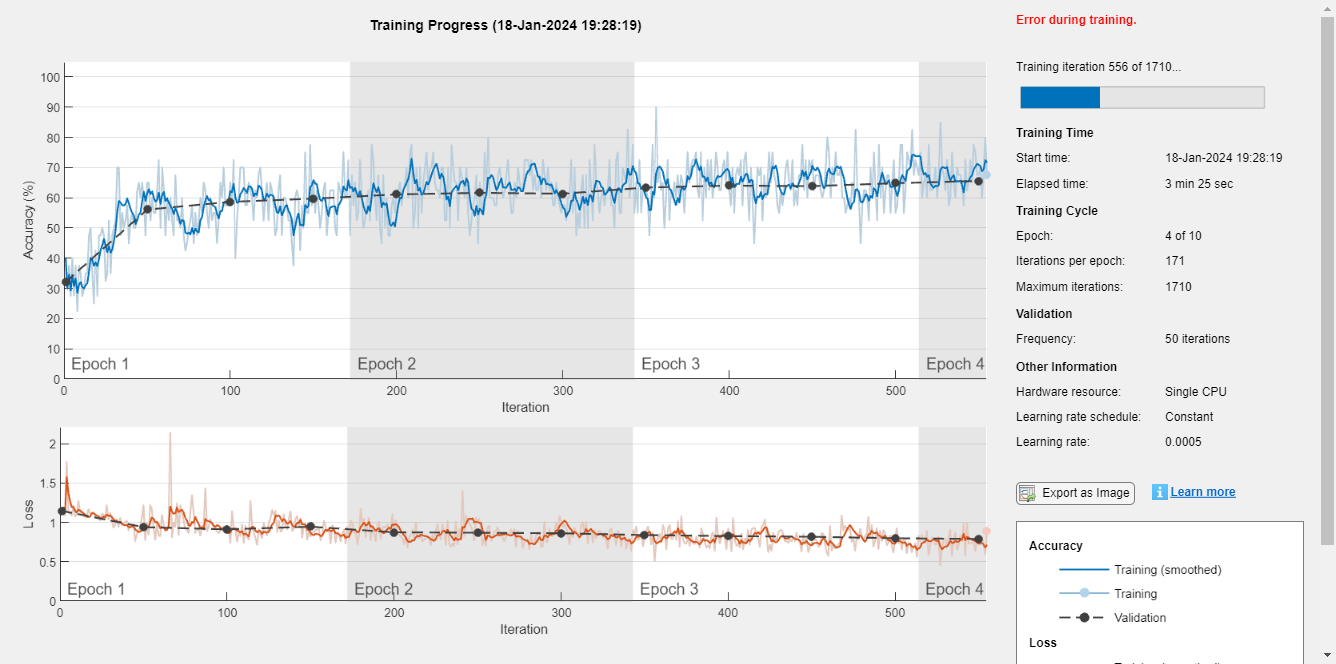

eeg_net = trainNetwork(train_imds,layers,options);

## Testing Trained Network

Finally, classification accuracy is tested against the testing data and expressed as the percentage of correct classifications.

[YPred,err] = classify(eeg_net, train_imds); performance1 = sum(0+ (train_imds.Labels == YPred))/length(YPred);
[YPred,err] = classify(eeg_net, val_imds  ); performance2 = sum(0+ (  val_imds.Labels == YPred))/length(YPred);
[YPred,err] = classify(eeg_net, test_imds ); performance3 = sum(0+ ( test_imds.Labels == YPred))/length(YPred);
fprintf('Percent correct training   is %1.2f %%\n', performance1*100);

Percent correct training   is 81.12 %


fprintf('Percent correct validation is %1.2f %%\n', performance2*100);

Percent correct validation is 65.90 %


fprintf('Percent correct testing    is %1.2f %%\n', performance3*100);

Percent correct testing    is 63.80 %


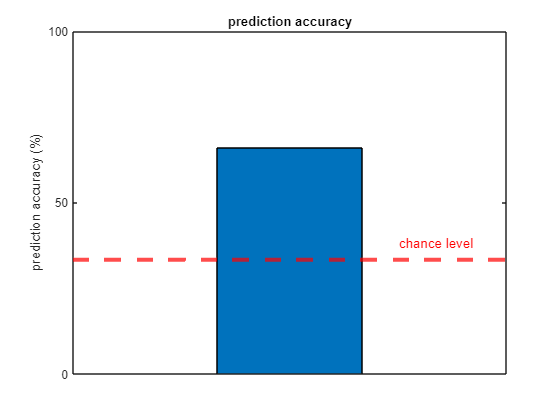

figure;bar(performance2*100);
title('prediction accuracy')
yline(mean(classProportions)*100,'r--','LineWidth',3);
ylabel('prediction accuracy (%)');
xticks([]);yticks([0 50 100]);yticklabels({'0','50','100'});ylim([0 100])
txt = 'chance level';
text(1.6, 5 + mean(classProportions)*100,txt,'Color','r')

**Contributors:**

### **References**

[1] Gorgolewski, K., Esteban, O., Schaefer, G., Wandell, B. and Poldrack, R., 2017. OpenNeuro—a free online platform for sharing and analysis of neuroimaging data. *Organization for human brain mapping. Vancouver, Canada*, *1677*(2).

[2] Delorme, A. and Makeig, S., 2004. EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis. *Journal of neuroscience methods*, *134*(1), pp.9-21.

[3] Pernet, C.R., Appelhoff, S., Gorgolewski, K.J., Flandin, G., Phillips, C., Delorme, A. and Oostenveld, R., 2019. EEG-BIDS, an extension to the brain imaging data structure for electroencephalography. *Scientific data*, *6*(1), p.103.

### **Helper Functions**

function check_correspondence(label_info_sorted, imds, row_selected)

selected_files = label_info_sorted.Var1(row_selected);
imds_files     = imds.Files;
non_correspondence = 0;

for iFile = 1:length(selected_files)
    if isempty(strfind(imds_files{iFile}, selected_files{iFile}(3:end)))
        error('Mismatch at position %d, label %s and folder %s', iFile, imds.Files{1}, selected_files{iFile}(3:end));
        non_correspondence = 1;
    end
end

if non_correspondence == 0
    disp('All the samples correspond to labels')
end

end


function [ALLEEG] = highpassfilt(ALLEEG, freq, srate)
                     
nyq_freq = srate / 2;

[B, A] = cheby1(4, 0.1, freq/nyq_freq, 'high');


for i = 1:numel(ALLEEG)
    for ii = 1:size(ALLEEG(i).data,1)
       raw_lfp = ALLEEG(i).data(ii,:);
       ALLEEG(i).data(ii,:) =  single(filtfilt(B, A, double(raw_lfp)));
    end
end
end


function [classProportions, uniqueLabels] = compute_class_proportions(imds)

classes = unique(imds.Labels);
uniqueLabels = cellstr(unique(imds.Labels));
allLabels = cellstr(imds.Labels);

for iCat = 1:length(uniqueLabels)
    n(iCat) = sum(cellfun(@(x)isequal(uniqueLabels{iCat}, x), allLabels));
end
classProportions = n/sum(n);

end


function [imds_bal] = create_balanced_dataset(imds)

[classProportions, uniqueLabels] = compute_class_proportions(imds);

drop_factor = round(classProportions/min(classProportions));

labels = imds.Labels;

% for x = 1:numel(uniqueLabels)
%     class_ind{x} = labels(find(classProportions==classProportions(x)));
% end

for x = 1:numel(uniqueLabels)
count=1;
for i = 1:numel(imds.Files)
    if imds.Labels(i) == uniqueLabels{x}
        class_ind{x}(count)=i;
        count=count+1;
    end
end
drop_ind{x} = class_ind{x};
drop_ind{x}(1:drop_factor(x):end) = [];
end

drop_ind_all = cell2mat(drop_ind);

imds_bal = imds;
imds_bal.Files(drop_ind_all)=[];


end


function dataset_info(ALLEEG)


count=1;
for i = 1:numel(ALLEEG)   
            dur_rec(count) = round(size(ALLEEG(i).data,2)/ALLEEG(i).srate);
            count=count+1;
end
min_dur_rec = min(dur_rec);
max_dur_rec = max(dur_rec);

eeg_ch_count=0;
for i = 1:numel(ALLEEG(1).chanlocs)
    if strcmp(ALLEEG(1).chanlocs(i).type,'EEG')==1
        eeg_ch_count=eeg_ch_count+1;
    end
end

fprintf('The example consists of %d datasets, recorded from %d unique subjects.\nIndividual datasets consist of %d channels recorded at %d Hz. Recording durations are %d-%d sec.',numel(ALLEEG), numel(unique({ALLEEG(:).subject})), eeg_ch_count, ALLEEG(1).srate, min_dur_rec, max_dur_rec)

end